clc;clear;

Ts=0.4713;Tr=0.1044;a=0.0005;g=atand(1/3);ks=1.29e-7*100*3600;q=2.85e-6*100*3600/ks-3.35e-8*100*3600/ks/cosd(g);Fae=0;p=-3.35e-8*100*3600/ks/cosd(g);
% A=2.68e-8;B=-1.112e-4;C=0.3269;
A=0;B=0;C=0.34;
H=1*100*a*cosd(g);
bm=load('bm18.txt');
bn=load('bn18.txt');
bs=load("bm18.txt");


tic
tp1=5.27;tq1=24-tp1;
tp=tp1*ks*a*cosd(g)^2/(Ts-Tr);
tq=tq1*ks*a*cosd(g)^2/(Ts-Tr);
ZJ=21;ZT=48;
k=zeros(ZT+1,ZJ);
f=zeros(ZT+1,ZJ);
v=zeros(ZT+1,ZJ);
T=zeros(ZT+1,ZJ);
parfor i=0:ZT
    t=ks*a*i*cosd(g)^2/(Ts-Tr);   
for j=1:ZJ
    z=(j-1)/(ZJ-1)*H;
    W=0;
    for s=1:1000
        Fs=0;
        for n=1:1000
            Fn=0;
            for m=1:1000
            E1=exp(-tp/4)*(2*(((C-Tr)*sin(bm(m)*H)*exp(0.5*H)/(Ts-Tr)+B*(sin(bm(m)*H)*exp(0.5*H)*H-((4*bm(m)+(3-4*bm(m)*bm(m))*sin(bm(m)*H)*exp(0.5*H))/(1+4*bm(m)*bm(m))))/((Ts-Tr)*a*cosd(g))+A*(sin(bm(m)*H)*exp(0.5*H)*H*H-2*((16*bm(m)*(2*cos(bm(m)*H)*exp(0.5*H)-1)/(1+4*bm(m)*bm(m))+(3-4*bm(m)*bm(m))*H*sin(bm(m)*H)*exp(0.5*H))/(1+4*bm(m)*bm(m))))/((Ts-Tr)*a*a*cosd(g)*cosd(g)))*exp(-bm(m)*bm(m)*tp)*(0.25+bm(m)*bm(m))+q*exp(0.5*H)*(bm(m)*cos(bm(m)*H)+0.5*sin(bm(m)*H))*(exp(0.25*tp)-exp(-bm(m)*bm(m)*tp)))/((0.25+bm(m)*bm(m))*(1+(0.25+bm(m)*bm(m))*H)));
            Fn=Fn+((bm(m)*sin(bn(n)*H)-bn(n)*sin(bm(m)*H))/(2*(bm(m)^2-bn(n)^2))-bm(m)*bn(n)*(cos(bm(m)*H)-cos(bn(n)*H))/(bm(m)^2-bn(n)^2))*E1;  
            end
            F1=2*((bn(n)^2+0.25)*exp(-(bn(n)^2+0.25)*(tq))*Fn+exp(H/2)*(1-exp(-(bn(n)^2+0.25)*(tq)))*bn(n))/(H*(bn(n)^2+0.25)+0.5);
            Fs=Fs+F1*(0.5*(bn(n)*sin(bs(s)*H)-bs(s)*sin(bn(n)*H))-bn(n)*bs(s)*(cos(bn(n)*H)-cos(bs(s)*H)))/(bn(n)^2-bs(s)^2);
        end
        W=W+2*(bs(s)*cos(bs(s)*z)+0.5*sin(bs(s)*z))*(exp(-bs(s)^2*t)*(bs(s)^2+0.25)*Fs+p*exp(H/2)*(bs(s)*cos(bs(s)*H)+0.5*sin(bs(s)*H))*(exp(0.25*t)-exp(-bs(s)^2*t)))/(H*(bs(s)^2+0.25)+1)/(bs(s)^2+0.25);

    end
        k(i+1,j)=W*exp(-0.5*z-0.25*t);
        f(i+1,j)=(log(k(i+1,j))/a-Fae*100)/100;
        v(i+1,j)=k(i+1,j)*ks/100/3600;
        if W*exp(-0.5*z-0.25*t)*(Ts-Tr)+Tr<Ts
            T(i+1,j)=W*exp(-0.5*z-0.25*t)*(Ts-Tr)+Tr;
        else
            T(i+1,j)=Ts;
        end
end
end
toc

历时 199.606251 秒。


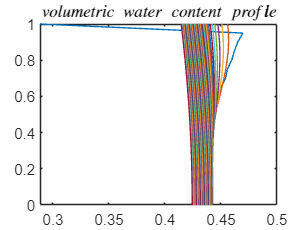

for j=1:ZJ
z(j)=(j-1)/(ZJ-1)*H/a/100/cosd(g);
end
for i=0:1:ZT
x(i+1,:)=T(i+1,:);
y2=z(1,:);
plot(x(i+1,:),y2)
title('$volumetric \ water \ content \ profile$','Interpreter','latex')
hold on;
end
hold off;

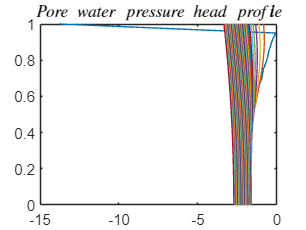

for i=0:1:ZT
x1(i+1,:)=f(i+1,:);
y=z(1,:);
plot(x1(i+1,:),y)
title('$Pore \ water \ pressure \ head \ profile$','Interpreter','latex');
hold on;
end
hold off;

for i=1:ZT
    x2(i,:)=((f(i+1,21)-f(i+1,20))/0.1+cosd(g))*ks*10;
    x3(i,:)=sum(x2(1:i));
end
t1=1:ZT

t1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48


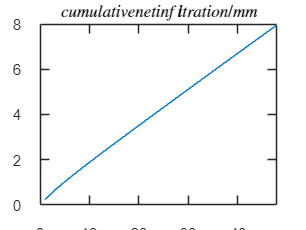

plot(t1,x3)
title('$cumulative net infiltration/mm$','Interpreter','latex')

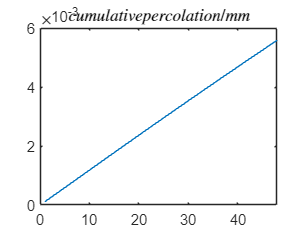


for i=0:ZT-1
v1(i+1,1)=v(i+2,1);
v2(i+1,1)=sum(v1(1:i+1))*1000;
end
plot(t1,v2)
title('$cumulative percolation/mm$','Interpreter','latex')
hold off;

c=5.74;f1=26.6;fb=14.1;rd=14.2;rw=9.81;H1=1.0;
uw=f*9.81;
g1=T*0.01*rw;
for i=1:ZT+1
    for j=1:100
        z(j)=(j-1)/100*H1;
        g2=g1(i,:);
        FOS(i,j)=(c-uw(i,j)*tand(fb))/((rd*(H1-z(j))+sum(g2(j:100)))*tand(g))+tand(f1)/tand(g);        
    end
end

索引超过数组元素的数量。索引不能超过 21。

for i=1:ZT+1
x4(i,:)=FOS(i,:);
y=z(1,:);
plot(x4(i,:),y)
ylim([0 0.8])

hold on;
end
title('$FOS$','Interpreter','latex')
hold off;
